# Esercizio 1

Dato il sistema descritto dalla seguente funzione di trasferimento:


$$G\left(s\right)=\frac{5}{s\;\left(s+2\right)\;\left(s+5\right)}$$


progettare un regolatore standard digitale in grado di garantire:

- Errore nullo rispetto ad un riferimento a gradino

- Sovra-elongazione percentuale massima pari al 15% e tempo di assestamento minore di 2 sec

Passi da svolgere:

(a) Implementare in Simulink il sistema

(b) Tarare i parametri per regolatori standard del tipo PD,PI o PID, ipotizzando di NON conoscere il modello dell'impianto

(c) Discretizzare i regolatori ottenuti dopo opportuna scelta del tempo di campionamento

## Taratura Regolatori

Per poter ottenere i parametri dei regolatori ipotizzando di non conoscere il modello preciso dell'impianto è necessario osservare la risposta del sistema ed applicare il Metodo di Ziegler-Nichols adeguato.

Sarà necessario tarare un regolatore PID o PI poiché è necessario raggiungere l'annullamento dell'errore rispetto al gradino

Analizzo quindi il sistema a ciclo aperto

clc
clear
close all

s=tf('s');
Gs = 5/(s*(s+2)*(s+5))

Gs =
 
          5
  ------------------
  s^3 + 7 s^2 + 10 s
 
Continuous-time transfer function.
Model Properties



zpk(Gs)

ans =
 
        5
  -------------
  s (s+5) (s+2)
 
Continuous-time zero/pole/gain model.
Model Properties


pole(Gs)

ans =      0
    -5
    -2


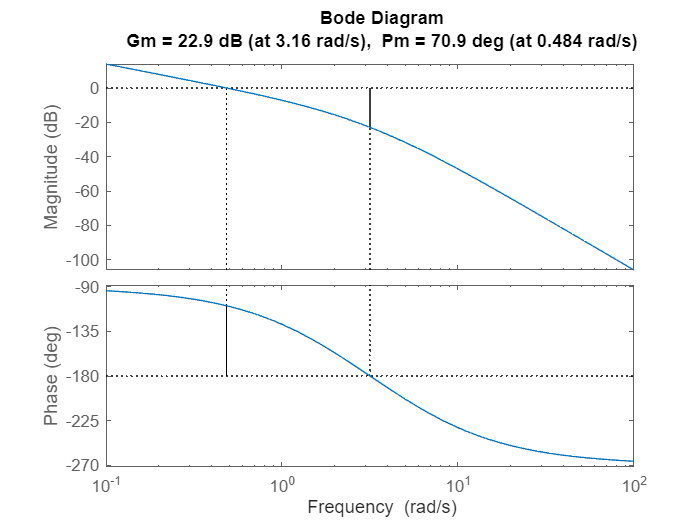

margin(Gs)

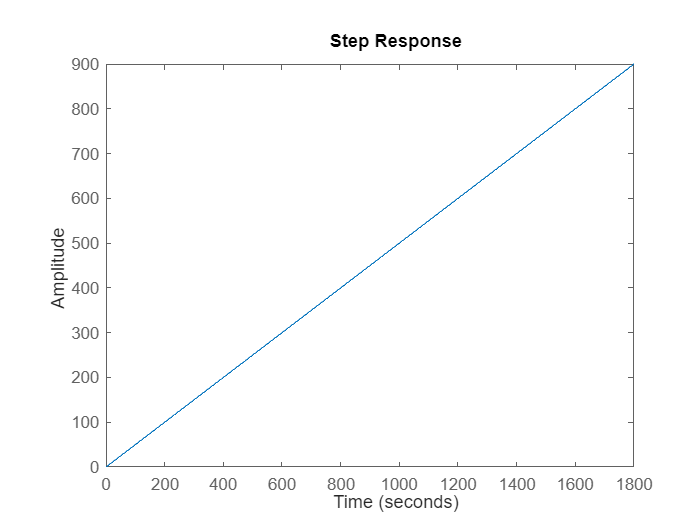

step(Gs)

Il sistema non è BIBO stabile ed infatti la risposta al gradino a ciclo aperto è instabile, sarà dunque necessario applicare il metodo di Ziegler Nichols a ciclo chiuso per ottenere il K critico e conseguentemente i parametri iniziali per tarare il PID.

(Pt 1 Simulink)

La funzione di trasferimento di un controllore PID si può scrivere come:


$$C\left(s\right)=K_p \left(1+\frac{1}{T_i \;s}+T_d \;s\right)$$
 

dove $T_d s$ viene approssimato come $\frac{T_d s}{1+\frac{T_d }{N}s}$ con N tipicamente tra 3 e 20

I valori di conversione proposti da Ziegler e Nichols sono

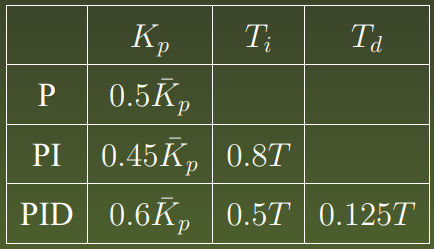

Avendo quindi $K_{\textrm{cr}} =14$ e $T=1\ldotp 990\;\sec$ si ottengono i seguenti parametri del regolatore PID:


$$\begin{array}{l}
K_p =8\ldotp 4\\
T_i =0\ldotp 995\\
T_d =0\ldotp 2487
\end{array}$$


Una prima implementazione del regolatore è dunque $C\left(s\right)=8\ldotp 4\left(1+\frac{1}{0\ldotp 995\;s}+0\ldotp 24875\;s\right)=8\ldotp 4+\frac{8\ldotp 4422}{s}+2\ldotp 0891s$

(Pt 2 Simulink)

A seguito del processo di taratura del PID si è giunti alla seguente formulazione del regolatore:

$C\left(s\right)=9\ldotp 5+\frac{1}{s}+7s$    da cui:


$$K_p =9\ldotp 5$$
    
$$T_i =9\ldotp 5$$
    
$$T_d =0\ldotp 737$$


Cs=((9.5)+(1/s)+(7*s))

Cs =
 
  7 s^2 + 9.5 s + 1
  -----------------
          s
 
Continuous-time transfer function.
Model Properties


Ls=Cs*Gs

Ls =
 
  35 s^2 + 47.5 s + 5
  --------------------
  s^4 + 7 s^3 + 10 s^2
 
Continuous-time transfer function.
Model Properties


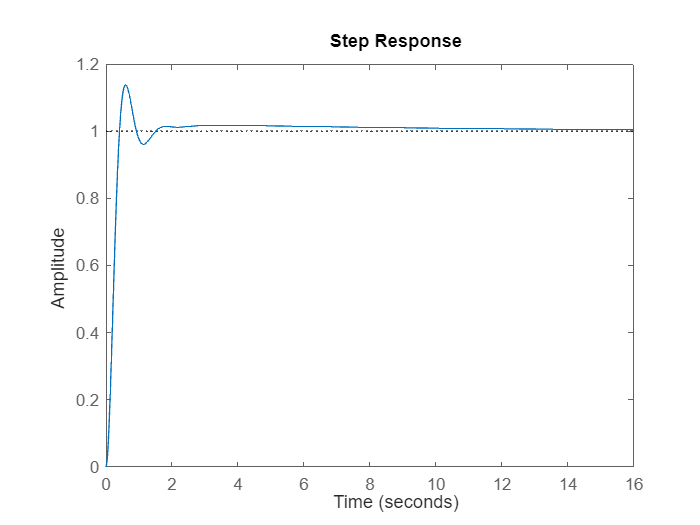

step(feedback(Ls,1))

stepinfo(feedback(Ls,1))

ans = struct with fields:
         RiseTime: 0.2778
    TransientTime: 1.3450
     SettlingTime: 1.3450
      SettlingMin: 0.9526
      SettlingMax: 1.1380
        Overshoot: 13.7999
       Undershoot: 0
             Peak: 1.1380
         PeakTime: 0.6075


## Discretizzazione del regolatore

I controllori PID digitali vengono ottenuti dai PID analogici per discretizzazione.

Solitamente si discretizza il termine integrale con la trasformazione di Tustin e quello derivativo con Eulero in avanti.


$$C\left(s\right)=K_p \left(1+\frac{1}{T_i \;s}+T_d \;s\right)$$


$C\left(z\right)=K_p \left(1+\frac{T}{{2T}_i \;}\;\frac{z+1}{z-1}+\frac{T_d }{T}s\;\frac{z-1}{z}\right)$ dove $T$ è il tempo di campionamento

Una buona approssimazione del tempo di campionamento può essere effettuata a partire dalla pulsazione naturale del sistema come $T=\frac{\omega_n }{10}$

Ricavo quindi il valore della pulsazione a partire dalle informazioni ottenute dalla risposta al gradino


$$\delta=\frac{1}{\sqrt{1+\left(\frac{\pi}{\log(S)}\right)^2}}$$


S = 0.14

S = 0.1400

ts=1.35

ts = 1.3500

d = 1/sqrt(1+(pi/log(S))^2)

d = 0.5305


$$t_s =\frac{3}{\delta \omega_n }\;\to \;\omega_n =\frac{3}{t_s \delta }$$


omega_n=3/(ts*d)

omega_n = 4.1889

Scelgo un tempo di capionamento pari a $T=0\ldotp 4$ 